clear all
clc

% Homework 2 - Problem 1 case x1
% Student Name: Giuditta Sigona
% Created on 16/04/2022
% Last version xx/yy/zz

% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;

%parameters
m1=1000;
m2=10;
k=0.001; %coeff plastica acciaio
B=0.5;

%systems
x1 = (m2*s^2+B*s-k)/((s^2)*(m1*m2*s^2+B*(m1+m2)*s-k*m1))

x1 =
 
   10 s^2 + 0.5 s - 0.001
  -------------------------
  10000 s^4 + 505 s^3 - s^2
 
Continuous-time transfer function.



x2 = (B*s-k)/((s^2)*(m1*m2*s^2+B*(m1+m2)*s-k*m1));
diff = m2/(m1*m2*s^2+B*(m1+m2)*s-k*m1);

% ************* case x1 *******************

zpk(x1)   % factorized into the zero-pole-gain form

ans =
 
  0.001 (s+0.05193) (s-0.001926)
  ------------------------------
   s^2 (s+0.05241) (s-0.001908)
 
Continuous-time zero/pole/gain model.



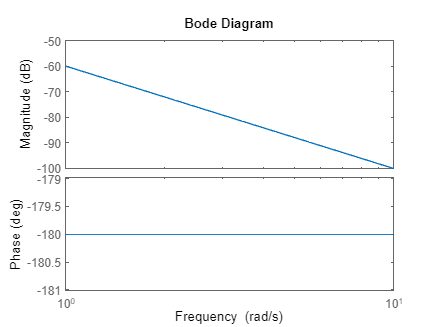

approx = tf(0.001/s^2);
% bode(approx)

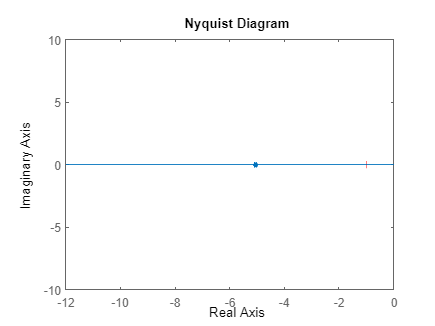

% nyquist(approx)

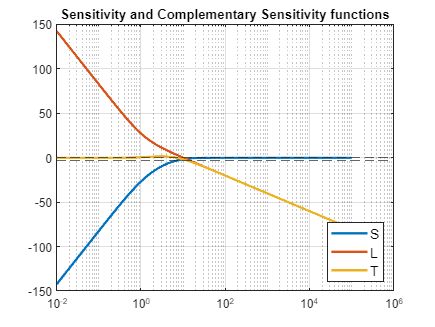

% tf1=(minreal(x1))  %ricuce 0 e poli uguali

% Sensitivity Bode plot
Cont = pidtune(x1,'pid');

Loop=loopsens(x1,Cont);

[magS0,phaseS0]=bode(Loop.Si,om);
[magT0,phaseT0]=bode(Loop.Ti,om);
[magL0,phaseL0]=bode(Loop.Li,om);

figure(5)
Plot1 = semilogx(om,20*log10(magS0(1,:)),...
    om,20*log10(magL0(1,:)),...
    om,20*log10(magT0(1,:))); grid
set(Plot1,'LineWidth',2)
yline(0,'--')
yline(-3, '--')
legA = legend('S','L','T','Location','SouthEast');
set(legA,'FontSize',12)
title('Sensitivity and Complementary Sensitivity functions')

Stable = Loop.Stable

Stable = 0

% *********** H-inf controller *********

A1 = 7.9*10^-8; % low frequency behavior of specs of |S| (the value associated to S(0) )
wBS1 = 8; % is the lower bound on B3S
M1 = 1; %is the upper bound for |S(jω)|, generally belongs to [1.4, 2] - peak of S
wS1 = (s / M1+wBS1)/(s+wBS1*A1);

%Controller design through mixsyn 
[C1,CL1,GAM1] = mixsyn(x1,wS1,[]);     %controller with only Ws
GAM1

GAM1 = 1.3120e+06

SF1 = loopsens(x1,C1);
tf(C1)

ans =
 
    -114.6 s^4 - 6.007 s^3 - 5.331e-05 s^2 - 1.211e-08 s - 1.48e-12
  --------------------------------------------------------------------
  s^5 + 0.1599 s^4 + 0.01018 s^3 + 0.1149 s^2 + 0.005956 s + 3.764e-09
 
Continuous-time transfer function.



SF1.Stable

ans = 1

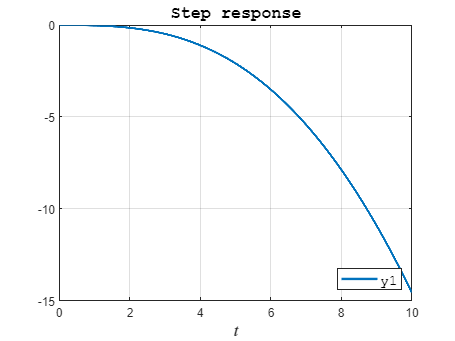


y1 = step(SF1.Ti,t);
Plot2 = plot(t,y1); grid
set(Plot2,'LineWidth',2);
legend('y1','FontName','courier','FontSize',12,'Location','SouthEast')
xlabel('$t$','Interpreter','latex','FontSize',14)
title('Step response H-inf controller','FontName','courier','FontSize',14)


% Find alpha
syms a b c d e f g h alpha s 

numP =((m2*s^2 + B*s -k)/(m1*m2));
denP = (s^4 + (B*(m1+m2)*s^3/(m1*m2)) - (k*m1*s^2/(m1*m2)));
P = numP/denP

$$P = \frac{\frac{s^{2}}{1000}+\frac{s}{20000}-\frac{1}{10000000}}{s^{4}+\frac{101\,s^{3}}{2000}-\frac{s^{2}}{10000}}$$


numC =(a*s^3 + b*s^2 + c*s + d);
denC = (s^4+e*s^3+f*s^2+g*s+h);
C = numC/denC  % Strictly proper controller m<n

$$C = \frac{a\,s^{3}+b\,s^{2}+c\,s+d}{s^{4}+e\,s^{3}+f\,s^{2}+g\,s+h}$$


p_s= numC*numP + denC*denP

$$p\_s = \left(\frac{s^{2}}{1000}+\frac{s}{20000}-\frac{1}{10000000}\right)\,\left(a\,s^{3}+b\,s^{2}+c\,s+d\right)+\left(s^{4}+\frac{101\,s^{3}}{2000}-\frac{s^{2}}{10000}\right)\,\left(s^{4}+e\,s^{3}+f\,s^{2}+g\,s+h\right)$$

p_s=vpa(collect(p_s))

$$p\_s = s^{8}+\left(e+0.0505\right)\,s^{7}+\left(0.0505\,e+f-0.0001\right)\,s^{6}+\left(0.001\,a-0.0001\,e+0.0505\,f+g\right)\,s^{5}+\left(0.00005\,a+0.001\,b-0.0001\,f+0.0505\,g+h\right)\,s^{4}+\left(0.00005\,b-0.0000001\,a+0.001\,c-0.0001\,g+0.0505\,h\right)\,s^{3}+\left(0.00005\,c-0.0000001\,b+0.001\,d-0.0001\,h\right)\,s^{2}+\left(0.00005\,d-0.0000001\,c\right)\,s-0.0000001\,d$$


p_star=(s+alpha*(1+j))^4*(s+alpha*(1-j))^4;   % p*(s)
p_star=collect(p_star)

$$p\_star = s^{8}+\left(8\,\alpha \right)\,s^{7}+\left(32\,\alpha^{2}\right)\,s^{6}+\left(80\,\alpha^{3}\right)\,s^{5}+\left(136\,\alpha^{4}\right)\,s^{4}+\left(160\,\alpha^{5}\right)\,s^{3}+\left(128\,\alpha^{6}\right)\,s^{2}+\left(64\,\alpha^{7}\right)\,s+16\,\alpha^{8}$$


eq1= e + 0.0505 == 8*alpha;
eq2= 0.0505*e + f - 0.0001 == 32*alpha^2;
eq3= 0.001*a - 0.0001*e + 0.0505*f + g == 80*alpha^3;
eq4= 0.00005*a + 0.001*b - 0.0001*f + 0.0505*g + h == 136*alpha^4;
eq5= 0.00005*b - 0.0000001*a + 0.001*c - 0.0001*g + 0.0505*h == 160*alpha^5;
eq6= 0.00005*c - 0.0000001*b + 0.001*d - 0.0001*h == 128*alpha^6;
eq7= 0.00005*d - 0.0000001*c == 64*alpha^7;
eq8= - 0.0000001*d == 16*alpha^8;

sol = solve([eq1, eq2, eq3, eq4, eq5, eq6, eq7, eq8], [e,f,a,b,g,h,c,d]);
a = vpa(sol.a)

$$a = -83200000000000000.0\,\alpha^{8}-640000000000000.0\,\alpha^{7}-2560000000000.0\,\alpha^{6}-272000000.0\,\alpha^{4}+8080000.0\,\alpha^{3}-169616.0\,\alpha^{2}+2222.202\,\alpha -14.557700125$$

b = vpa(sol.b)

$$b = -4361600000000000.0\,\alpha^{8}-33600000000000.0\,\alpha^{7}-129280000000.0\,\alpha^{6}-320000000.0\,\alpha^{5}-16000.0\,\alpha^{3}+323.2\,\alpha^{2}-4.2404\,\alpha +0.027777525$$

c = vpa(sol.c)

$$c = -80000000000.0\,\alpha^{8}-640000000.0\,\alpha^{7}$$

d = vpa(sol.d)

$$d = -160000000.0\,\alpha^{8}$$

e = vpa(sol.e)

$$e = 8.0\,\alpha -0.0505$$

f = vpa(sol.f)

$$f = 32.0\,\alpha^{2}-0.404\,\alpha +0.00265025$$

g = vpa(sol.g)

$$g = 83200000000000.0\,\alpha^{8}+640000000000.0\,\alpha^{7}+2560000000.0\,\alpha^{6}+272000.0\,\alpha^{4}-8000.0\,\alpha^{3}+168.0\,\alpha^{2}-2.201\,\alpha +0.0144188125$$

h = vpa(sol.h)

$$h = 4320000000000.0\,\alpha^{8}+33280000000.0\,\alpha^{7}+128000000.0\,\alpha^{6}+320000.0\,\alpha^{5}+16.0\,\alpha^{3}-0.3232\,\alpha^{2}+0.0042404\,\alpha -0.000027777525$$


% 
% alpha_A=vpa(solve(a==0,alpha))
% alpha_B=vpa(solve(b==0,alpha))
% alpha_C=vpa(solve(c==0,alpha))
% alpha_D=vpa(solve(d==0,alpha))
% alpha_E=vpa(solve(e==0,alpha))
% alpha_F=vpa(solve(f==0,alpha))
% alpha_G=vpa(solve(g==0,alpha))
% alpha_H=vpa(solve(h==0,alpha))



% pick alpha
s = tf('s');
alpha1 = 0,009;

alpha1 = 0


a1 = eval(subs(a,alpha,alpha1));  % eval convert symbol to value
b1 = eval(subs(b,alpha,alpha1));
c1 = eval(subs(c,alpha,alpha1));
d1 = eval(subs(d,alpha,alpha1));
e1 = eval(subs(e,alpha,alpha1));
f1 = eval(subs(f,alpha,alpha1));
g1 = eval(subs(g,alpha,alpha1));
h1 = eval(subs(h,alpha,alpha1));

C1 =(a1*s^3 + b1*s^2 + c1*s + d1)/(s^4+e1*s^3+f1*s^2+g1*s+h1);
L1=loopsens(x1,C1)

L1 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [8×1 double]
    Stable: 0


poli = L1.Poles

poli = 	1.0e+-3 *

  -0.6621 + 0.0000i
  -0.4682 + 0.4713i
  -0.4682 - 0.4713i
   0.0110 + 0.6625i
   0.0110 - 0.6625i
   0.4690 + 0.4486i
   0.4690 - 0.4486i
   0.6385 + 0.0000i


Stabilita = L1.Stable

Stabilita = 0


% pick alpha
s = tf('s');
alpha2 = 0,01;

alpha2 = 0


a2 = eval(subs(a,alpha,alpha2));  % eval convert symbol to value
b2 = eval(subs(b,alpha,alpha2));
c2 = eval(subs(c,alpha,alpha2));
d2 = eval(subs(d,alpha,alpha2));
e2 = eval(subs(e,alpha,alpha2));
f2 = eval(subs(f,alpha,alpha2));
g2 = eval(subs(g,alpha,alpha2));
h2 = eval(subs(h,alpha,alpha2));

C2 =(a2*s^3 + b2*s^2 + c2*s + d2)/(s^4+e2*s^3+f2*s^2+g2*s+h2);
L2=loopsens(x1,C2)

L2 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [8×1 double]
    Stable: 0


L2.Stable

ans = 0


% pick alpha
s = tf('s');
alpha3 = 0,1;

alpha3 = 0


a3 = eval(subs(a,alpha,alpha3));  % eval convert symbol to value
b3 = eval(subs(b,alpha,alpha3));
c3 = eval(subs(c,alpha,alpha3));
d3 = eval(subs(d,alpha,alpha3));
e3 = eval(subs(e,alpha,alpha3));
f3 = eval(subs(f,alpha,alpha3));
g3 = eval(subs(g,alpha,alpha3));
h3 = eval(subs(h,alpha,alpha3));

C3 =(a3*s^3 + b3*s^2 + c3*s + d3)/(s^4+e3*s^3+f3*s^2+g3*s+h3);
L3=loopsens(x1,C3)

L3 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [8×1 double]
    Stable: 0


L3.Stable

ans = 0


% pick alpha
s = tf('s');
alpha4 = 1;

a4 = eval(subs(a,alpha,alpha4));  % eval convert symbol to value
b4 = eval(subs(b,alpha,alpha4));
c4 = eval(subs(c,alpha,alpha4));
d4 = eval(subs(d,alpha,alpha4));
e4 = eval(subs(e,alpha,alpha4));
f4 = eval(subs(f,alpha,alpha4));
g4 = eval(subs(g,alpha,alpha4));
h4 = eval(subs(h,alpha,alpha4));

C4 =(a4*s^3 + b4*s^2 + c4*s + d4)/(s^4+e4*s^3+f4*s^2+g4*s+h4);
L4=loopsens(x1,C4)

L4 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [8×1 double]
    Stable: 0


L4.Stable

ans = 0

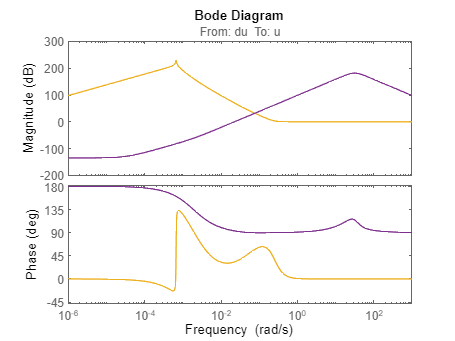



figure(2)
bode(L1.Si,L2.Si, L3.Si,L4.Si)

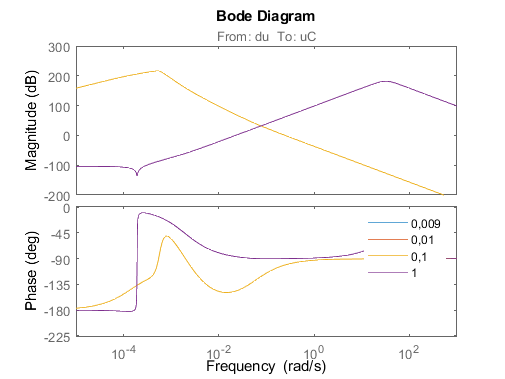

bode(L1.Ti,L2.Ti, L3.Ti, L4.Ti)
legend('0,009','0,01', '0,1', '1')

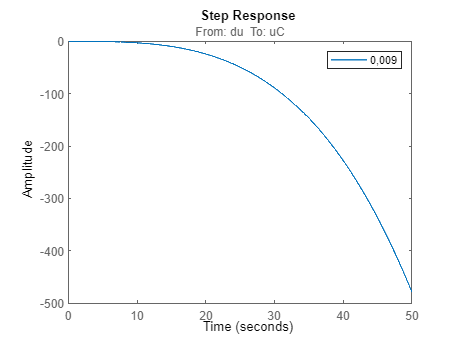


figure(3)
step(L1.Ti)
yline(1,'--')
legend('0,009')

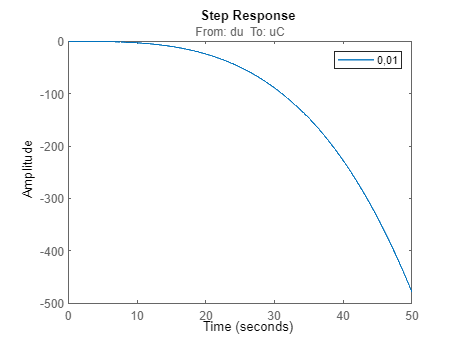


step(L2.Ti)
yline(1,'--')
legend('0,01')

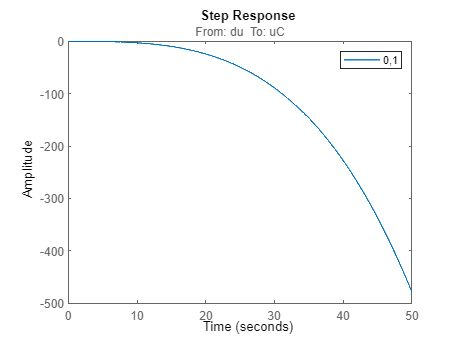


step(L3.Ti)
yline(1,'--')
legend('0,1')